Cleaning console

clear;
clc;

Setting file system variables

home = "/Users/edwinjoseph/Projects/leather-species-identification/";

source = strcat(home,"data/images/Test_grey/");

if not(isfolder(source))
   error(strcat("image source folder does not exist: ", source));
   exit(1);
end

target = strcat(home,"data/features/LBP_segregated/Test_grey/");
if not(isfolder(target))
   mkdir(target);
end

files = dir(source);
files = files(~ismember({files.name},{'.' '..'}));


File Management

% Radius of circular pattern used to select neighbors for each pixel in the input image, specified as the comma-separated pair consisting of 'Radius' and a positive integer. To capture detail over a larger spatial scale, increase the radius. Typical values range from 1 to 5.

% for radius=1:5
%     count = length(files);
% %     count = 4;
%     
%     species = strings(count, 1);
%     image_file_names = strings(count, 1);
%     data = [];
%     
%     for i=1:count
%         [filepath,name,ext] = fileparts(files(i).name);
%         
%     %     fileName
%         image_file_names(i) = name;
%     
%     %     species
%         if name(1)=='B'
%             species(i) = "Buff";
%         elseif name(1)=='C'
%             species(i) = "Cow";
%         elseif name(1)=='S'
%             species(i) = "Sheep";
%         elseif name(1)=='G'
%             species(i) = "Goat";
%         else
%             species(i) = "unknown";
%         end
%         
%         image = imread(strcat(source,files(i).name));
%         
%         data = [data; extractLBPFeatures(image,"Radius",radius)];
%     
%     end
%     message = "writing to file"
%     [rows,cols] = size(data);
%     
%     histogramHeader = "histogram"+(1:cols)
%     
%     saveAs = sprintf("%s/LBP_radius_%d.csv", target, radius);
%     header = table(["file" "species" histogramHeader]);
%     T = table([image_file_names(1:count) species(1:count) data]);
%     writetable([header; T], saveAs, 'WriteVariableNames', false);
% end

Extract a matrix/image for LBP

% image = imread(strcat(source, "buff/BBTS8 (96).jpg"));
% image = imread(strcat(source, "cow/CBTS9 (99).jpg"));
image = imread(strcat(source, "sheep/SBTS6 (90).jpg"));
% image = imread(strcat(source, "goat/GBTS5 (84).jpg"));

% image = randi(1024,1280)

dimension = size(image)

dimension =         1024        1280


% The radius at which the bit pattern is read
radius = 1

radius = 1

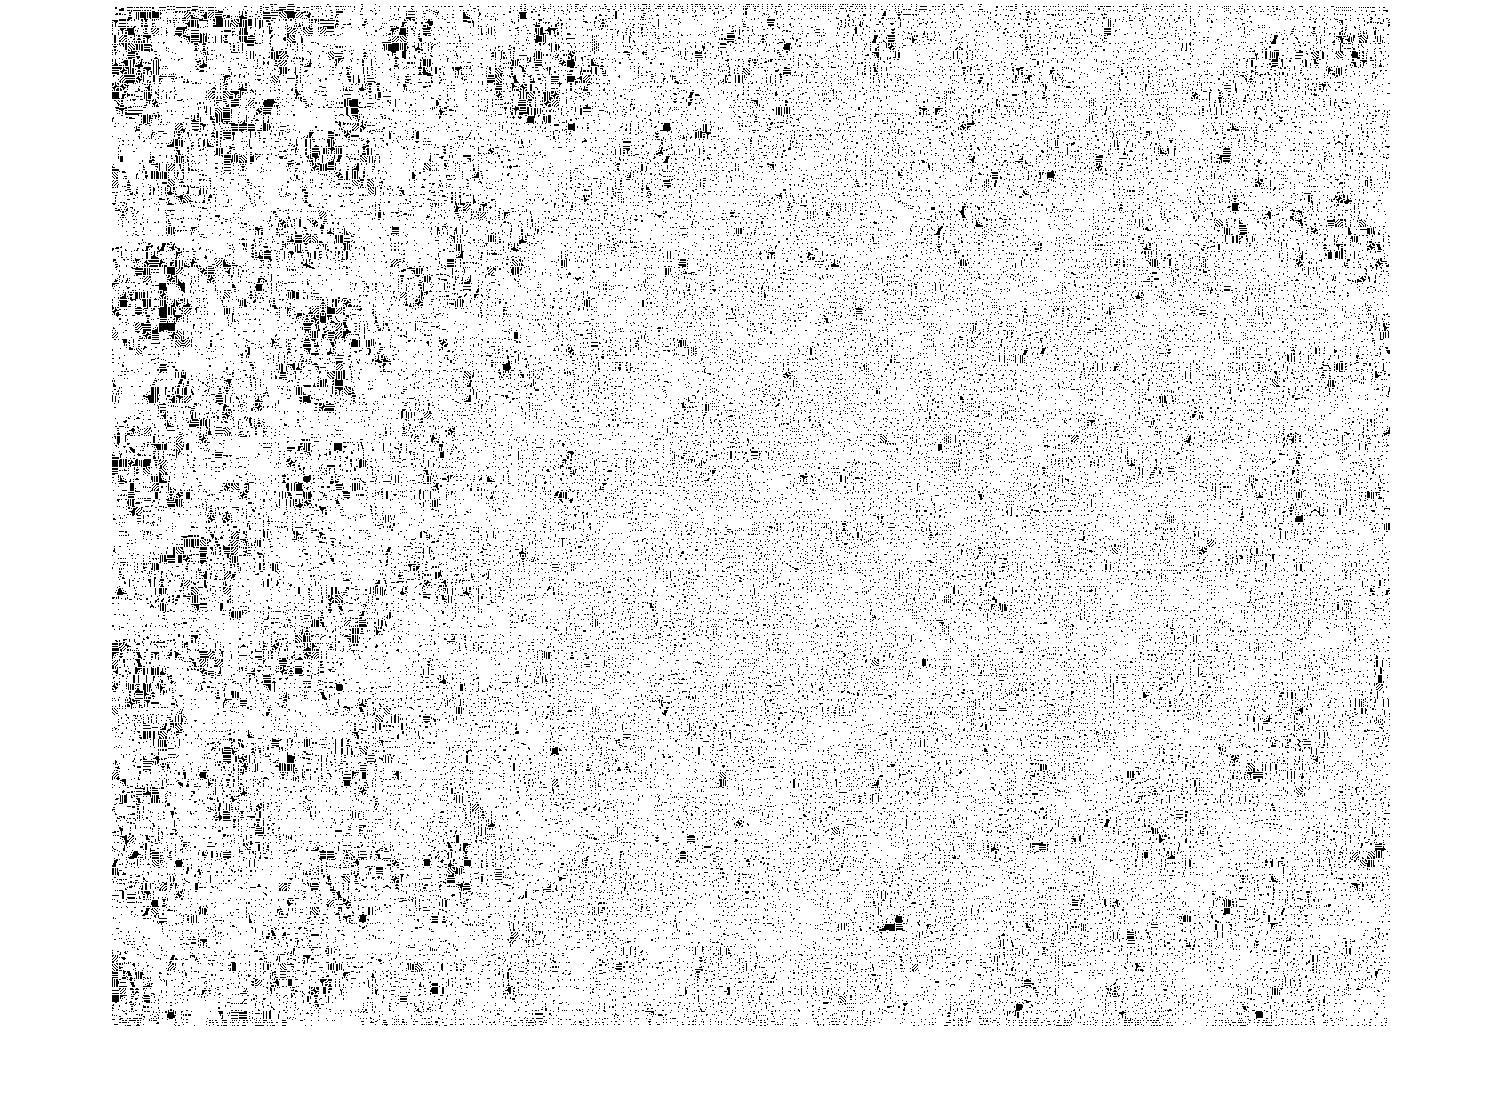

if (2*radius>=dimension(1) || 2*radius>=dimension(2))
   error("radius too big for image");
end

output = zeros(dimension(1)-2*radius, dimension(2)-2*radius);

for i=radius+1:dimension(1)-radius
    for j=radius+1:dimension(2)-radius
%         calculating bit pattern
        pattern = 0;
        
%         left to right (top)
        for k=-radius:radius-1
            if image(i-radius,j+k)>image(i,j)
                bit = 1;
            else 
                bit = 0;
            end
            
            pattern = bitshift(pattern, 1);
            pattern = pattern + bit;
        end
        
%         top to bottom (right)
        for k=-radius:radius-1
            if image(i+k,j+radius)>image(i,j)
                bit = 1;
            else 
                bit = 0;
            end
            
            pattern = bitshift(pattern, 1);
            pattern = pattern + bit;
        end
        
%         right to left (bottom)
        for k=-radius:radius-1
            if image(i+radius,j-k)>image(i,j)
                bit = 1;
            else 
                bit = 0;
            end
            
            pattern = bitshift(pattern, 1);
            pattern = pattern + bit;
        end
        
%         bottom to top (left)
        for k=-radius:radius-1
            if image(i-k,j-radius)>image(i,j)
                bit = 1;
            else 
                bit = 0;
            end
            
            pattern = bitshift(pattern, 1);
            pattern = pattern + bit;
        end
        
        output(i-1, j-1) = pattern;
    end
end
imshow(output)